**A little statistics**

**Part 1**

checking the error function

normcdf(0)

ans = 0.5000

normcdf(0.1)

ans = 0.5398

normcdf(0.24)

ans = 0.5948

checking the inverse of the error function

norminv(0.5)

ans = 0

norminv(0.5398)

ans = 0.0999

norminv(0.5948)

ans = 0.2399

values match pretty close to inputs

check probabilities for sigma = 1,2,5

norminv(0.8413)

ans = 0.9998

norminv(0.9772)

ans = 1.9991

norminv(0.9999999)

ans = 5.1993

close!

negative numbers would appear if we try

probability that is below 0.5

norminv(0.3)

ans = -0.5244

The integral goes from negative inf to z, and probability of 1/2 is at z=0. The negative makes sense because it assumes that we are looking to the right of the mean centered at 0, hence things on the left would be negative

**Part2**

I will be showing a plot of randomly generated points for a lognormal distribution (in blue), and plotted over it an actual lognormal distribution (in orange). The lognormal is dominated by values mu and sigma, which make up how widespread the distribution is and how quicklyit may fall off.

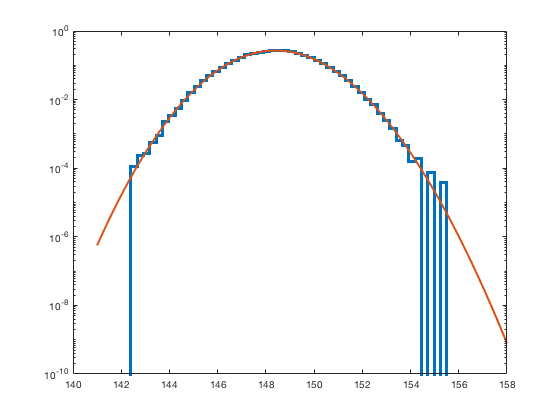

dist = random('Lognormal',5.,0.01,[1,100000]);
histogram(dist,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf");
hold on
x = linspace(141,158,1000);
pd = makedist("Lognormal","mu",5.,"sigma",0.01);
plot(x,pdf(pd,x),"LineWidth",2);
set(gca,'YScale','log');

**Part 3**

A)

value = 151

B)

What is the probability that the measurement of value 151 isn't noise or is not produced by the signal free distribution, instead being a physical measurement, if higher is signal-like

Another way to see this is the probability that the selected value or anything smaller is given by the probability distribution

C) Math description

integral from -inf to 151 of pd (probability distribution)

D)

cdf(pd,151)

ans = 0.9580

E) convert this probability into sigma

norminv(0.9580)

ans = 1.7279

the sigma is 1.7279

**Part 4**

try values 148,140,200,166,120,150

The expectation is that values selected within the distribution will yield probabilities between 0 and 1, with values at the higher end yielding closer to 1, while values below the distribution yielding negative results.

see the associated sigmas

cdf(pd,148)

ans = 0.3902

norminv(cdf(pd,148))

ans = -0.2788

cdf(pd,140)

ans = 2.6773e-09

norminv(cdf(pd,140))

ans = -5.8358

cdf(pd,200)

ans = 1

norminv(cdf(pd,200))

ans = Inf

cdf(pd,166)

ans = 1

norminv(cdf(pd,166))

ans = Inf

cdf(pd,120)

ans = 1.6196e-100

norminv(cdf(pd,120))

ans = -21.2508

The results were largely as expected.

**Poison Distribution**

x = 0:10

x =      0     1     2     3     4     5     6     7     8     9    10


poisDist = makedist("Poisson", 'lambda',7);

lambda is the main parameter in a Poisson distribution, changing lambda changes how "large" the distribution is

subplot(2,3,4)
stairs(x-2,pdf(poisDist,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 7, log plot');
subplot(2,3,5)
poisDist2 = makedist("Poisson",'lambda',4);
stairs(x-2,pdf(poisDist2,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 4, log plot');
subplot(2,3,6)
poisDist3 = makedist("Poisson",'lambda',15);
stairs(x-2,pdf(poisDist3,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 15, log plot');
subplot(2,3,1)
stairs(x-2,pdf(poisDist,x),"LineWidth",2);
title('lambda = 7');
subplot(2,3,2)
stairs(x-2,pdf(poisDist2,x),"LineWidth",2);
title('lambda = 4');
subplot(2,3,3)
stairs(x-6,pdf(poisDist3,x),"LineWidth",2);
title('lambda = 15');

changing x range well...changes the range that values of x may span, and thus the number of entries

x = 0:100

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


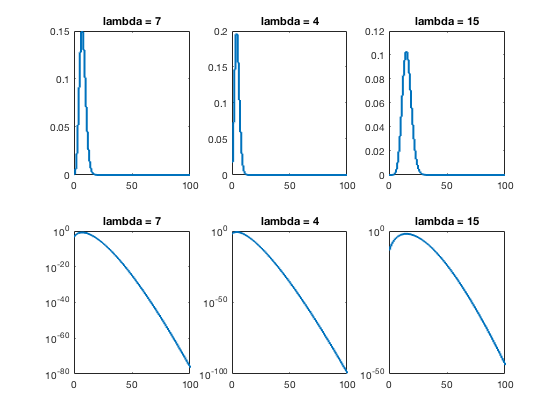

subplot(2,3,4)
stairs(x,pdf(poisDist,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 7');
subplot(2,3,5)
stairs(x,pdf(poisDist2,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 4');
subplot(2,3,6)
stairs(x,pdf(poisDist3,x),"LineWidth",2);
set(gca,'YScale','log');
title('lambda = 15');
subplot(2,3,1)
stairs(x,pdf(poisDist,x),"LineWidth",2);
title('lambda = 7');
subplot(2,3,2)
stairs(x,pdf(poisDist2,x),"LineWidth",2);
title('lambda = 4');
subplot(2,3,3)
stairs(x,pdf(poisDist3,x),"LineWidth",2);
title('lambda = 15');

**hypothetical question**

What is the probability that the measurement of value 6 isn't noise or is not produced by the signal free distribution, instead being a physical measurement, if higher is signal-like?

Another way to see this is the probability that the selected value or anything smaller is given by the probability distribution.

cdf(poisDist,6)

ans = 0.4497

norminv(cdf(poisDist,6))

ans = -0.1264

sigma value is given by result of norminv, so sigma is -0.1264

A negative sigma here has a similar meaning to the continuous case discussed in sections above, as the value integrated is to the left of the distribution "mean" value, hence yielding a negative sigma.

D)

The probabilities and sigmas being discrete implies that recording a ton of events and taking an average does not necessarily yield something of meaningful value — the average of 100 trials may be a result that cannot be achieved within any trial, thus representing incorrect probabilities and 'sigmas.' 

Since probabilities and sigmas, as well as measurement results, are all discrete values, it may be a bit harder to distinguish between what is made by a discrete distribution and what is a real measurement. However, one may take a very large sample of measurements, and compare the results of those measurements, which should yield a Gaussian distribution of the means of measurements, which can then be easier to interpret.

There is no issue with parameters being continuous, despite the distribution being discrete, because like with the example of the dice and mean, the sum of discrete values divided by the number of terms in no way has to be an integer, so in general, it will have a continuous spectrum.